% 4.1
load /Users/prayashdas/Downloads/HW3/hw3.mat
d1=hw3_2_1;
d2=hw3_2_2;

n =0;m=0;
k=10;
N=100;

for i=-4:0.1:8,
    n=n+1;m=0;
    for j=-4:0.1:8,
        m=m+1;
        dd=d1-[i;j]*ones(1,100);
        diss=sqrt(dd(1,:).^2+dd(2,:).^2);
        dis_sort=sort(diss);
        V1 = pi * dis_sort(k)^2;
        p1(n,m) = (k/N)/V1;
        if i==1 & j==-2
            p1x=p1(n,m)
        end
    end
end

p1x = 0.0276


        
n =0;m=0;
k=10;
N=100;


for i=-4:0.1:8,
    n=n+1;m=0;
    for j=-4:0.1:8,
        m=m+1;
        ddd=d2-[i;j]*ones(1,100);
        dis=sqrt(ddd(1,:).^2+ddd(2,:).^2);
        dis_sort=sort(dis);
        V2 = pi * dis_sort(k)^2;
        p2(n,m) = (k/N)/V2;
        if i==1 & j==-2
            p2x=p2(n,m)
        end
    end
end

p2x = 0.0010

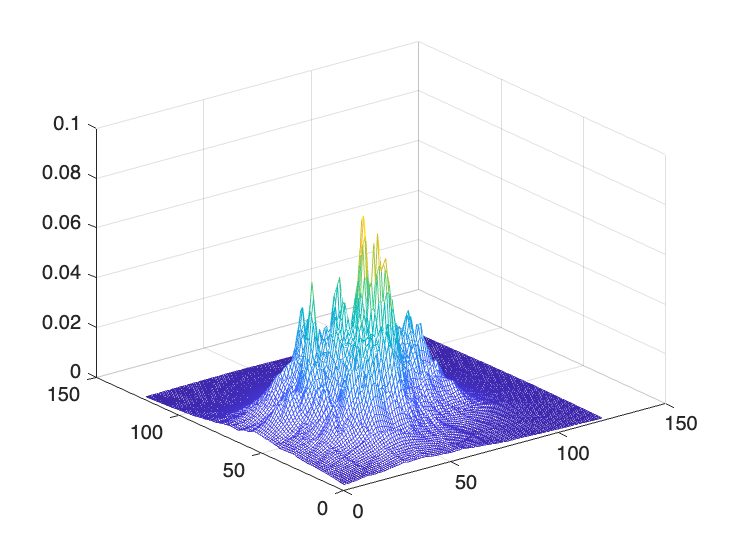




mesh(p1);

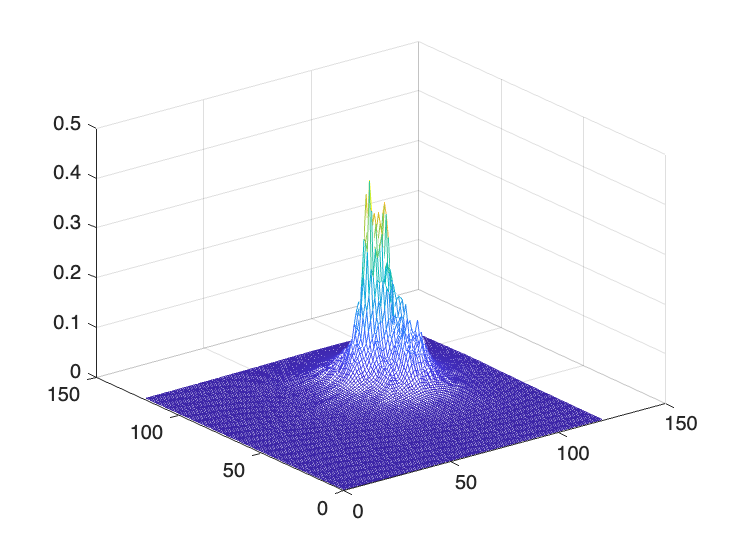

%hold;
figure
mesh(p2);


%classify point
pw1 = 0.5;
pw2 = 0.5;

if p1x * 0.5 > p2x * 0.5
    disp(" x = [1,-2]^t belongs to class1");
else
    disp(" x = [1,-2]^t belongs to class2");
end

 x = [1,-2]^t belongs to class1
